%% dSub NLX screening sandbox


% this is a simple sandbox for loading, and checking the spatial tuning
% properties of cells using NLX



%% add some code to the path
warning off 

if ~isunix
    addpath(genpath('C:\Users\williamslab\Documents\github\vandermeerlab\code-matlab\shared'));
    
    addpath(genpath('C:\Users\williamslab\Documents\github\CEH2'));
    data_dir = 'C:\Users\williamslab\Dropbox (Williams Lab)\Williams Lab Team Folder\Eric\dSubiculum\inProcess\M23_2021-07-02_OF';
    
else
    addpath(genpath('/home/williamslab/Documents/Github/CEH2'));
    addpath(genpath('/home/williamslab/Documents/Github/vandermeerlab/code-matlab/shared'));
    data_dir = '/home/williamslab/Dropbox (Williams Lab)/Williams Lab Team Folder/Eric/dSubiculum/inProcess/M23_2021-07-02_OF';
end

warning on
cd(data_dir); % go to the data folder specified above

Error using cd
Cannot CD to /home/williamslab/Dropbox (Williams Lab)/Williams Lab Team Folder/Eric/dSubiculum/inProcess/M23_2021-07-02_OF (Name is nonexistent or not a directory).

## load dada


% cfg.fc = {FindFile('*A.t')}
cfg.getTTnumbers = 0;
S = LoadSpikes(cfg);

LoadSpikes: Loading 2 files...


pos = MS_LoadPos([]);

LoadPos.m: 100.00% of samples tracked.




spd = getLinSpd([], pos)

getLinSpd: calculating linear speed from position data
............................!
............................!


spd = struct with fields:
     type: 'tsd'
    units: 'au'
     tvec: [1×18490 double]
     data: [1×18490 double]
    label: {'spd'}
      cfg: [1×1 struct]




% interpolate the spikes to match the time vector
spk_x = interp1(pos.tvec,pos.data(1,:),S.t{1},'linear');
spk_y = interp1(pos.tvec,pos.data(2,:),S.t{1},'linear');


## plot a raster in time

cfg_rast = [];
% cfg_rast.spkColor = '
MultiRaster([], S)

ans = struct with fields:
           S: {[1×1 struct]  [1×1 struct]}
    plotMode: 'spikes only'


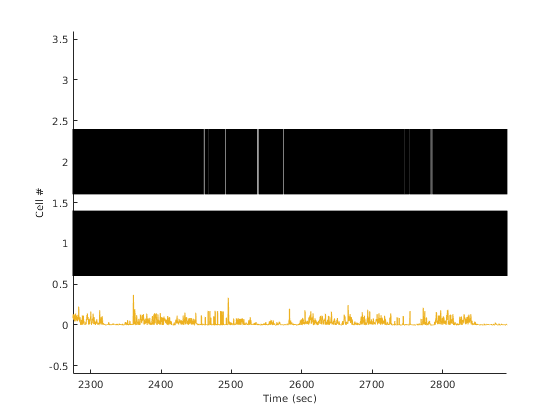


hold on
plot(spd.tvec, spd.data/1000)

## speed by spk correlations

% figure(104)

% scatter()




## generate an ISI histogram

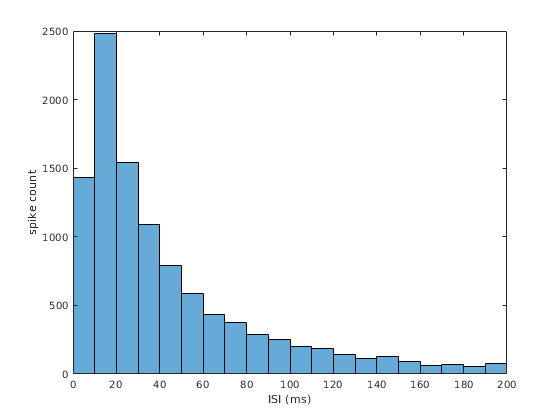


figure(102)
histogram(diff(S.t{1})*1000, 0:10:200)
xlabel('ISI (ms)')
ylabel('spike count')
xlim([0 200])

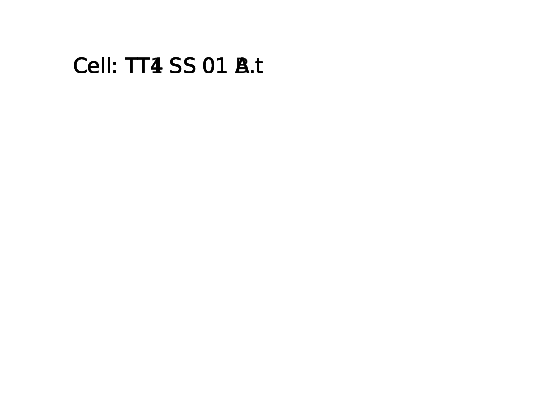


figure(103)
% plot(nan(10,10)); % blac
text(0, .9, ['Cell: ' strrep(S.label{1}, '_', ' ')], 'fontsize', 20);
axis off

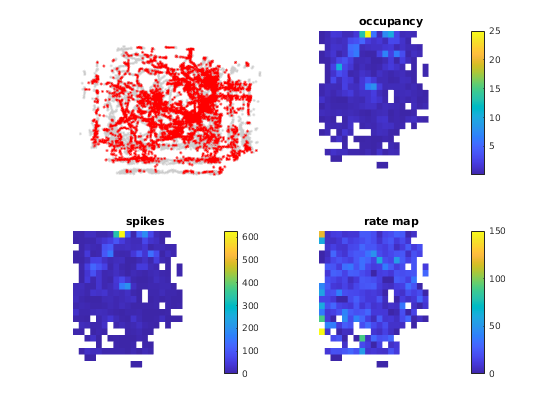

%% plot the position

figure(101)
subplot(2,2,1)

plot(pos.data(1,:), pos.data(2,:), '.', 'color', [0.8 0.8 0.8]);
hold on


S_idx = nearest_idx(S.t{2}, pos.tvec);
plot(spk_x,spk_y, '.r')
axis off
% convert to heat map. 

% set up binsclc
SET_xmin = 80; SET_ymin = 0; % set up bins
SET_xmax = ceil(max(pos.data(1,:))/10)*10; SET_ymax = ceil(max(pos.data(2,:))/10)*10;
SET_xBinSz = 20; SET_yBinSz = 20;
 
x_edges = SET_xmin:SET_xBinSz:SET_xmax;
y_edges = SET_ymin:SET_yBinSz:SET_ymax;
 


% compute occupancy
occ_hist = histcn(pos.data(1:2,:)',y_edges,x_edges); % 2-D version of histc()
 
no_occ_idx = find(occ_hist == 0); % NaN out bins never visited
occ_hist(no_occ_idx) = NaN;
 
occ_hist = occ_hist .* (1/30); % convert samples to seconds using video frame rate (30 Hz)
 
subplot(2,2,2)
pcolor(occ_hist); shading flat; axis off; colorbar
title('occupancy');

% get the spike map
spk_hist = histcn([spk_x, spk_y],y_edges,x_edges);
 
spk_hist(no_occ_idx) = NaN;
 
subplot(223)
pcolor(spk_hist); shading flat; axis off; colorbar
title('spikes');

% rate map
tc = spk_hist./occ_hist;
 
subplot(224)
pcolor(tc); shading flat; axis off; colorbar
title('rate map');
colormap('parula')

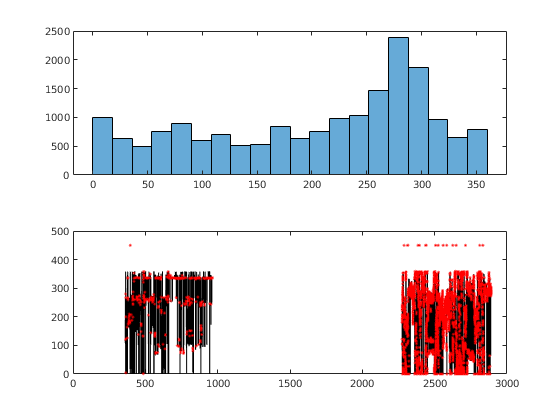

%% New Cell (heading info) 

hd_bin = 360/20;
hd_vec = 0:hd_bin:360;

keep_idx = pos.data(3,:)<=360;


figure(100)
subplot(2,1,1)
histogram(pos.data(3,keep_idx), hd_vec)
subplot(2,1,2)
plot(pos.tvec(keep_idx),pos.data(3,keep_idx), 'k')
hold on
plot(pos.tvec(S_idx), pos.data(3,S_idx), '.r')

%% compute HD

figure()
polarhistogram(pos.data(3,S_idx),360/20, 'DisplayStyle','stairs', 'edgecolor', 'b', 'linewidth', 4);
hold on

polarhistogram(pos.data(3,:), 360/20,  'DisplayStyle','stairs', 'edgecolor', [0.7 0.7 0.7], 'linewidth', 4)

legend({'Spikes', 'all'})

## speed and spiking relationships

figure(105)

scatter(spd.data(S_idx))
